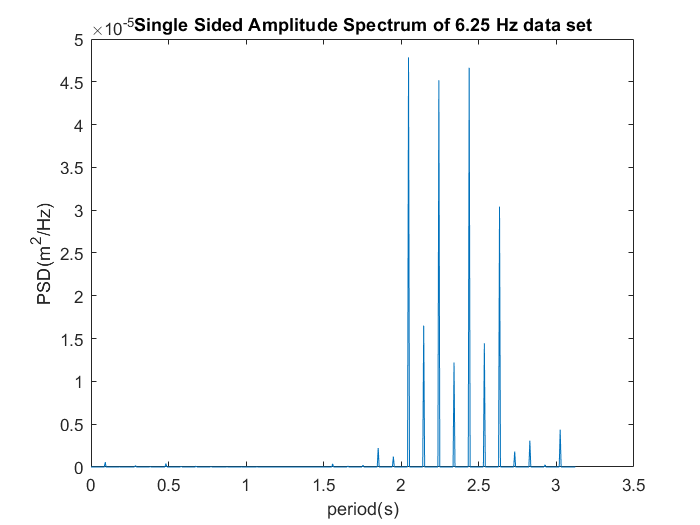

Textfile = load("PSD.txt");
writematrix(Textfile, "PSD.csv");
FFTData = readtable("PSD.csv");


N =  1024 - 1; 
FFTData = FFTData{:, 1}; %data is symmetric, *2 to account for contribution of other half 
fs = 6.25;
period = (fs*(0:(N/2))/(N));

plot(period(1:512), FFTData(1:512)/1024); %only plotting the real side of the dataset
title("Single Sided Amplitude Spectrum of 6.25 Hz data set");
xlabel("period(s)");
ylabel("PSD(m^2/Hz)");